# Boundary Conditions: Dirichlet BC

clear all, close all, clc
set_defaults()

## Example problem: Danube-Tisza Interfluve

The area is popuar for hydrological studies because the rivers run parallel for more than 100 km (see map) with very little change in elevation. This setup a geometry that can be approximated by a two-dimensional cross-section.

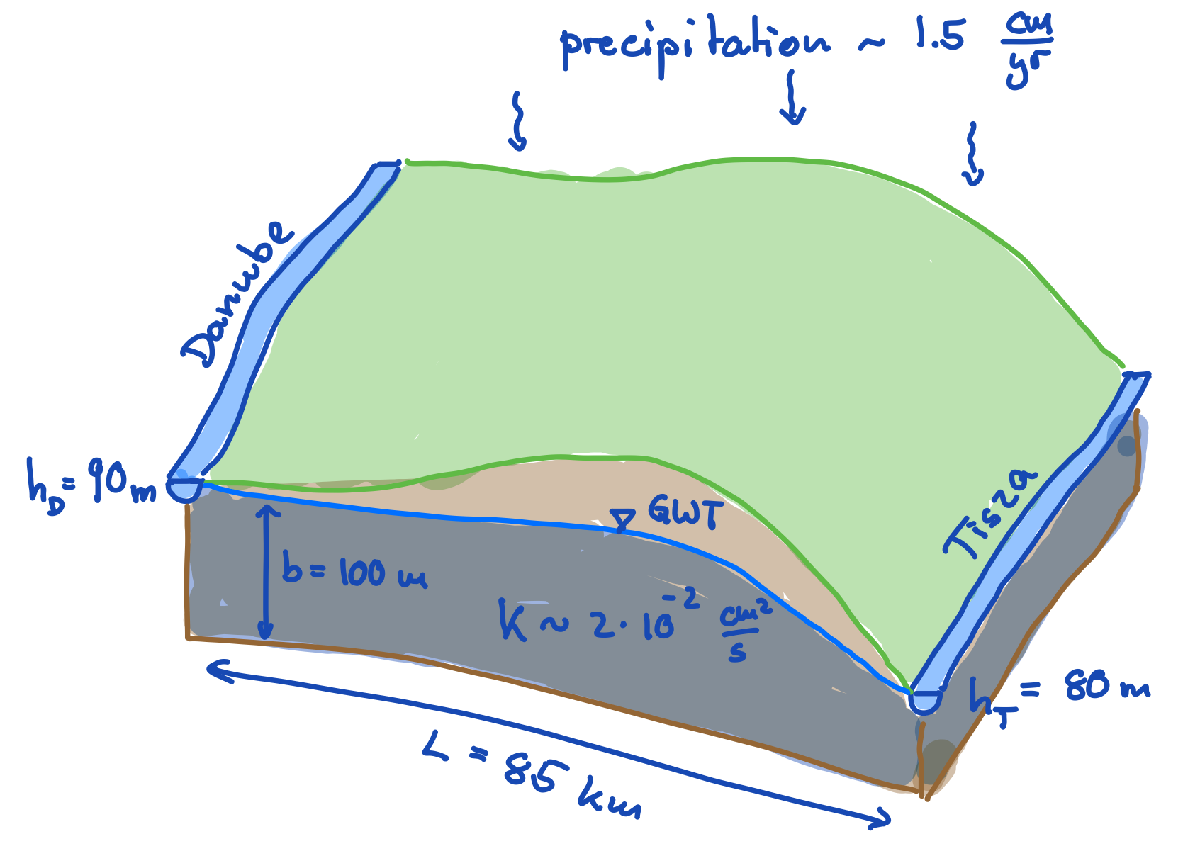

%% Physical properties
cm2m = 1/100;        % cm to m conversion
yr2s = 365*24*60^2;  % yr to s conversion

Length = 85070;      % Distance between Danube and Tisza rivers [m]
Width = 5430;        % Width of segment considered [m]
K =2e-2*cm2m;        % Hydraulic conductivity [m/s]
qp = 1.5*cm2m/yr2s;  % Average annual precipitation [m3/m2/s]
hD = 90;             % Elevation of Danube river[m]
hT = 80;             % Elevation of Tisza river [m]
b = 100;             % Aquifer thickness [m]

## Simplified shallow aquifer model

After vertically integrating we obtain the shallow aquifer model for the interfluve:

PDE:  $-\tilde{\nabla}\cdot\left[b\,K \tilde{\nabla} h\right] = q_r$ on $x \in \left[0,\, L\right]$

BC:    $h(0)=h_\mathrm{D} = 90$m   and  $h(x=L)=h_\mathrm{T} = 80$ m

Here the tilde on the divergence and gradient operators indicates that they only contain horizontal derivatives, because we have integrated in the vertical.

In 1D the PDE can also simply be written as


$$-\frac{\mathrm{d}}{\mathrm{d}x}\left[b\,K\frac{\mathrm{d}h}{\mathrm{d}x}\right]=q_p$$


and solved by integrating twice to obtain the following solutions for the head $h$ and flux $q$


$$h = h_D+\left(\frac{q_pL}{2bK}-\frac{h_D-h_T}{L}\right)x-\frac{q_p}{2bK}x^2$$



$$q=\frac{q_p}{b}\left(x-\frac{L}{2}\right)+\frac{K}{L}\left(h_D-h_T\right)$$


% Analytic solution
xa = linspace(0,Length,1e2);
ha = @(x,qp) hD + (qp*Length/2/b/K-(hD-hT)/Length)*x - qp/2/b/K*x.^2;
qa = @(x,qp) qp/b*(x-Length/2) + K/Length*(hD-hT);
xmax = @(qp) Length/2 - (K*b*(hD-hT))/(qp*Length);
qp_crit = 2*K*b*(hD-hT)/Length^2

qp_crit = 5.5272e-11

## Numerical solution

The head of a pore fluid, $h$, is given by the Poisson equation  

$-\nabla^2 h = \frac{q_p}{bK}$ on $x \in \left[0,\, L\right]$,

where $f_s$ is a source term and the two boundary condtions as applied heads of the Danube and Tisza rivers

$h(x=0) = h_{\mathrm{D}}$ and $h(x=L) = h_{\mathrm{T}}$.

Using discrete operators the partial differential equation can be discretized as follows

`L``*``h ``=`` fs`

where `L = -D*G` is the dicrete Laplacian operator, **h** is the unknown vector of temperatures and `fs` is the right hand side vector. Today we will discuss how to discretize the boundary condtions.

Without boundary conditions the problem is ill-posed and does not have a solution. This is reflected in the condition number of the discrete Laplacian operator, `L`.  

Grid.xmin = 0; Grid.xmax = Length; Grid.Nx = 20;
Grid = build_grid(Grid);
[D,G,C,I,M] = build_ops(Grid);
L = -D*G; % (assume unit thermal conductivity)
condest(L)

ans = Inf

A matrix with infinite condition number has no inverse. This is because there is an infinite number of possible solutions to the Laplace equation, only the boundary conditions (BC's) make the solution unique. 

Dirichlet BC's prescribe the solution on the boundary. In the discrete solution they prescribe the solution in the cells neighboring the boundaries. This constraint can be formulated as a linear system,

`B``*``h ``=`` g`

where `B` is the constrain matrix, `u` is the vector of unknowns (temperature), and **g** is a right hand side vector. The constrain matrix `B` is `Nc` by `Nx`, where `Nc` is the number of constraints, i.e., cells along Dirichlet boundaries with prescibed temperatures. This means that Dirichlet BC's provide constraints that reduce the overall number of unknown we need to solve for.

Therefore the boundary value problem is described by two linear systems

1) `L``*``h`` = ``fs`, arising from the PDE, where `L` is the `Nx` by `Nx` ***system matrix***

2) `B``*``h`` = ``g`, arising from the BC's, where **B** is the `Nc` by `Nx` ***constraint matrix***

Neither **L** nor **B** is invertible, both allow infinite solutions. To find the unique solution to the boundary value problem, the constraints in `B` must be eliminated from the system matrix `L`.

$\Rightarrow$**we need to understand how to eliminate constraints**

## Building the constraint matrix

Suppose we have the following two Nc by 1 column vectors:

- `dof_dir`: contains the degrees of fredom (dofs), i.e., cell numbers, of all cells along the Dirichlet boundary.

- `g`: contains the prescribed values the unknown is set to along the Dirichlet boundary.

The constraint matrix, **B**, needs to set the unknown in `dof_dir` to `g`. The matrix B therefore comprises the rows of the Nx by Nx identity matrix, `I`, that correspond to `dof_dir`. Therefore `B` can be built as follows

dof_dir = [Grid.dof_xmin;Grid.dof_xmax];
B = I(dof_dir,:);
size(B)

ans =      2    20


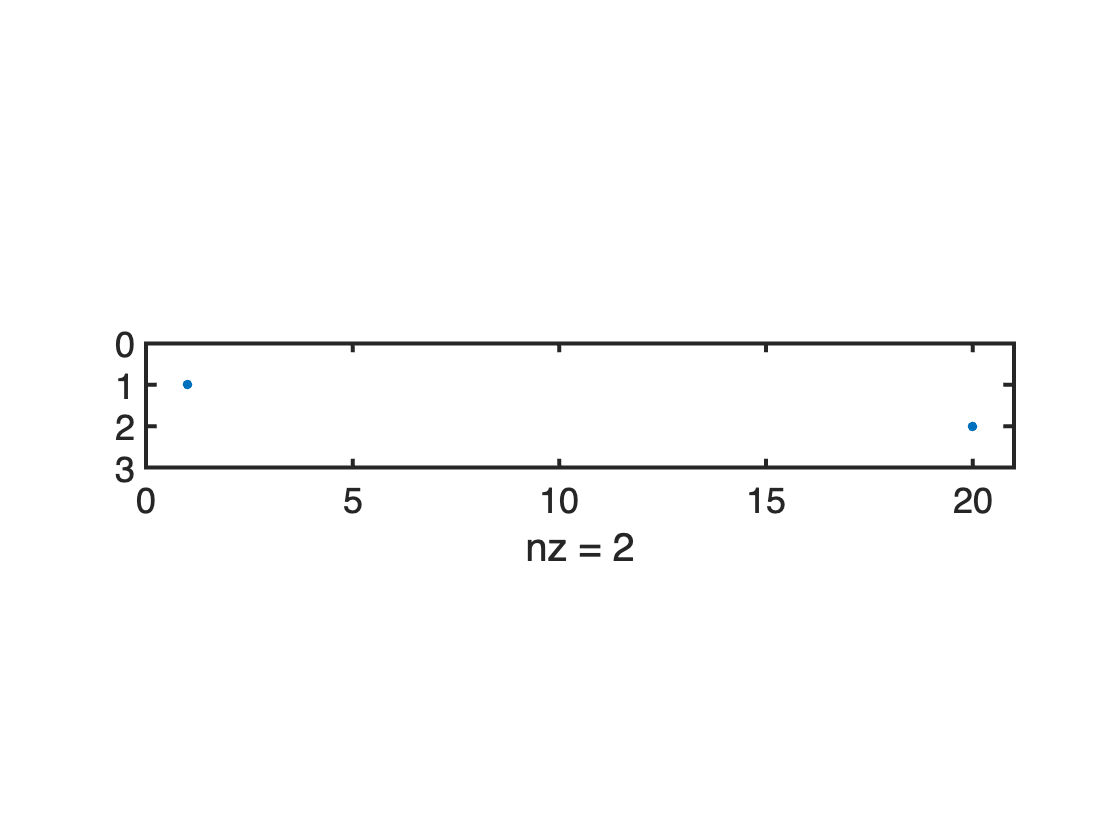

spy(B)

The resulting constraint matrix has one row for every cell that is set to a prescribed value by the Dirichlet BC's. In the 1D case with Diriclet BC's at both ends `Nc = 1` and `B` only has 2 rows. This simple construction will remain the same, even in higher dimensions.

# Homogeneous constraints

Initially, we consider a problem with homogeneous constraints, i.e., $h(x=0) = h(x=L)=0$. To have a non-trivial solution, i.e., $T(z) \neq 0$, with these boundary conditions we need a finite source term, $f_s\neq0$. Let's consider the following test problem

PDE: $-\nabla^2 h = \frac{q_p}{bK}$ on $x\in \left\lbrack 0,L\right\rbrack$,

BC's: $h(0) = h(1) = 0$,

with the analytic solution $T = \frac{1}{2}\left(x-x^2\right)$.

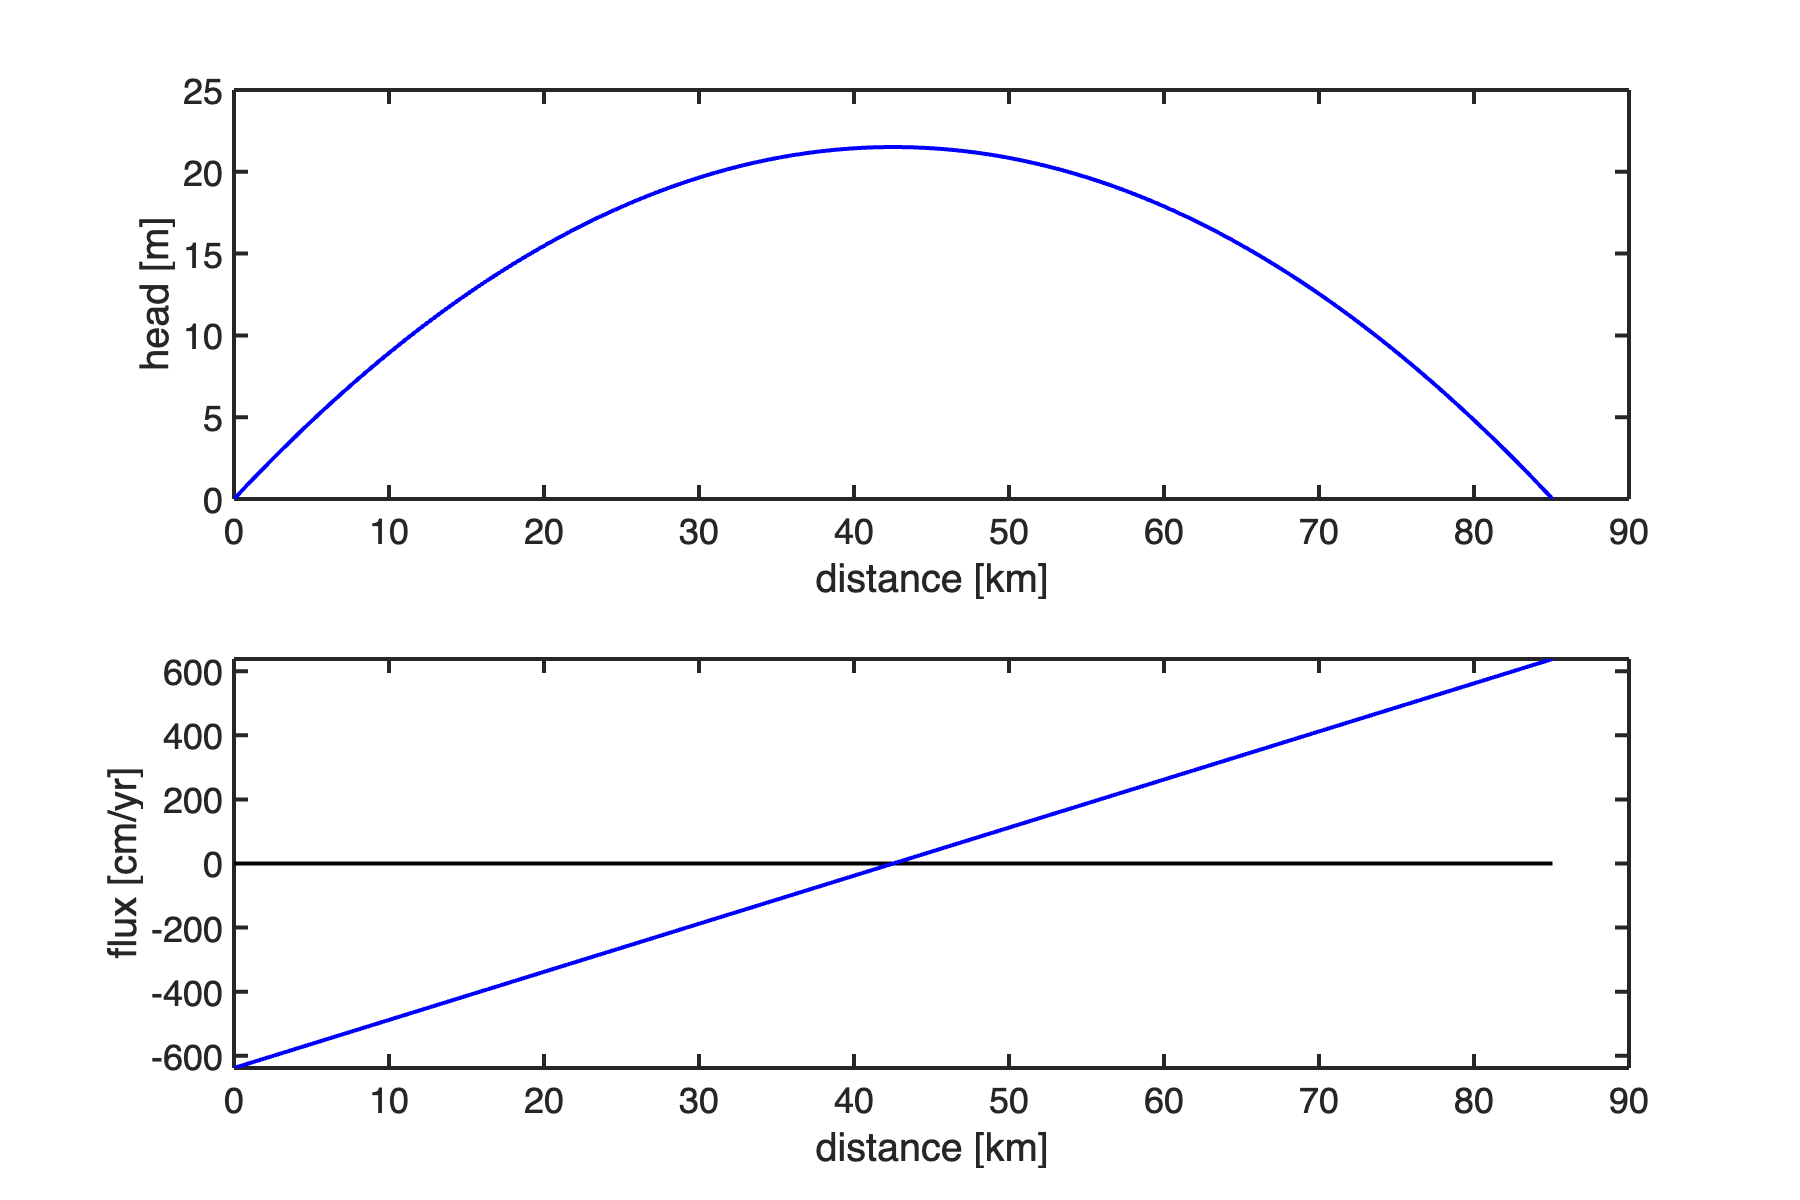

ha_hom = @(x,qp)  (qp*Length/2/b/K)*x - qp/2/b/K*x.^2;
qa_hom = @(x,qp) qp/b*(x-Length/2);
% u_ana = @(x) .5*(x-x.^2);
% x_ana = linspace(Grid.xmin,Grid.xmax,1e2);

figure('position',[10 10 900 600])
subplot 211
plot(xa/1e3,ha_hom(xa,qp),'b-'), hold on
xlabel 'distance [km]'
ylabel 'head [m]'

subplot 212
plot([0 Length]/1e3,[0 0],'k-'), hold on
plot(xa/1e3,qa_hom(xa,qp)/(cm2m/yr2s),'b-')
xlabel 'distance [km]'
ylabel 'flux [cm/yr]'

The discrete problem is then given by

PDE: `L``*``h`` = ``fs`

BC's: `B``*``h`` = ``0`

## **Reduced linear system**

Given that the constraints in `B` reduce the number of unknown we expect to solve a smaller or reduced linear system of size `(Nx-Nc)` by `(Nx-Nc)`

`Lr``*``hr ``=`` fsr.`

Here the variables are:

- `hr` is the (Nx-Nc) by 1 reduced vector of unknows.

- `fsr` is the (Nx-Nc) by 1 reduced r.h.s. vector.

- `Lr` is the (Nx-Nc) by (Nx-Nc) reduced system matrix.

## Projection matrix

What is the relation between **h** and **h**`r`, `fs` and `fsr`, and `L` and `Lr`? Two vectors of different length are related by a rectangular matrix

`u`` = ``N``*``hr` and `fs`` = ``N``*``fsr`

where `N` is a Nx by (Nx-Nc) matrix. Here **N** is any basis for the [nullspace](https://ocw.mit.edu/courses/mathematics/18-06-linear-algebra-spring-2010/video-lectures/lecture-6-column-space-and-nullspace/) of the constraint matrix **B**. The nullspace of **B** is simply the set of all solutions that satisfy `B``*``u`` = ``0`, i.e., all the possible solutions that satisfy the homogeneous boundary conditions.  If we search for solutions to `L``*``h``=``fs` in the nullspace of **B**, then the BC's are automatically satisfied. In Matlab the nullspace of a matrix can be found with the function [null()](https://www.mathworks.com/help/matlab/ref/null.html) or [spnull()](https://www.mathworks.com/matlabcentral/fileexchange/27550-sparse-null-space-and-orthogonal?focused=5152745&tab=function) for sparse matrices.

N = spnull(B);
size(N)

ans =     20    18


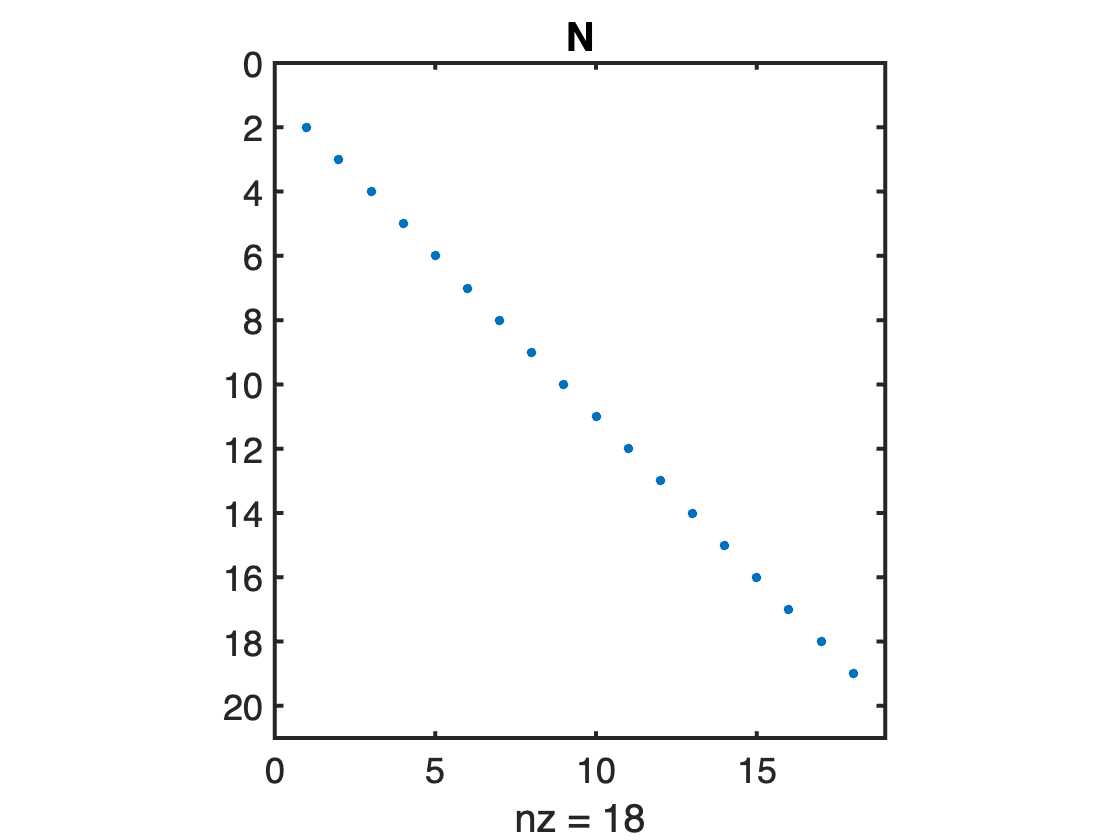


figure
spy(N), title 'N'

Assume that `N` is orthonormal, i.e., that the dot product between all columns is unity. the it follows that

- `N'``*``N`` = ``Ir`, where `Ir` is the `(Nx-Nc)` by `(Nx-Nc)` identity matrix in the reduced space.

- **N*****N'** = **Ic**, where Ic is the `Nx` by `Nx` "identity matrix" with `Nc` zeros on the diagonal.

Ir = N'*N;
size(Ir)

ans =     18    18


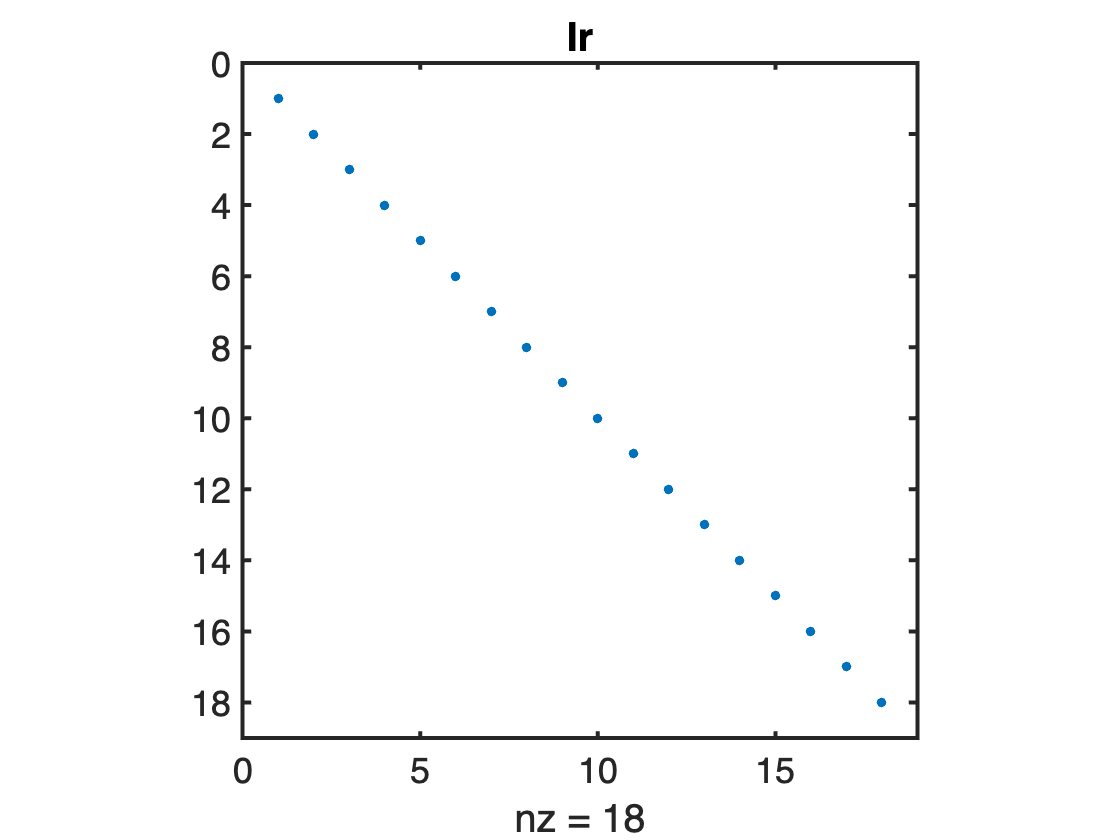

spy(Ir), title 'Ir'

non_0_entries_Ir = full(sum(diag(Ir)))

non_0_entries_Ir = 18


Ic = N*N';
size(Ic)

ans =     20    20


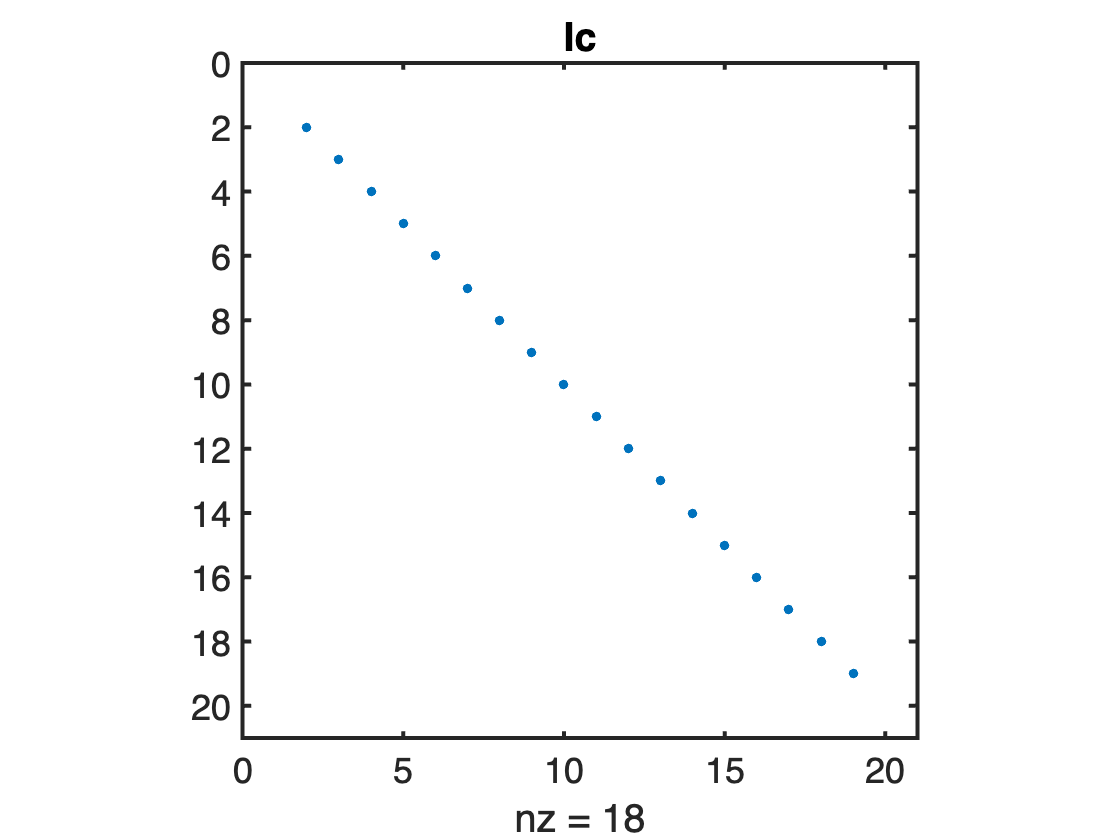

spy(Ic), title 'Ic'

non_0_entries_Ic = full(sum(diag(Ic)))

non_0_entries_Ic = 18

In this case, we have the following relationship, `N``'*``h`` = ``N``'*``N``*``hr`` = ``Ir``*``hr`` = ``hr`, so that `N` and `N`' allow us to go forth and back between `u` and `ur`:

`h`` = ``N``*``hr`

`hr`` = ``N``'*``h`

Of course, the same relationship exists between `fsr`` and ``fs, fsr ``=`` N``'*``fs`.

The matrix `N``'` *projects* the vector of unknowns into the nullspace of `B`. Note that a proper [projection matrix](https://ocw.mit.edu/courses/mathematics/18-06-linear-algebra-spring-2010/video-lectures/lecture-16-projection-matrices-and-least-squares/) is square, it would simply zero our the entries that are not in the nullspace. Instead, our `N``'` matrix eliminates these entries, but the idea is the same. 

## Reduced system matrix

Given the properties of N, defined above, the expression for the reduced system matrix is derived as follows

`L``*``h`` = ``fs`

`N``'*``L``*``h`` = ``N``'*``fs`

`N``'*``L``*``Ic``*``h`` = ``N``'*``fs`

`N``'*``L``*(``N``*`**N')**`*``h`` = ``N``'*``fs`

`(N``'*``L``*``N``)*(`**N'**`*``h)`` = ``N``'*``fs`

`Lr``*``hr`` = ``fsr`

where 

- `Lr`` = ``N``'*``L``*``N`

- `hr ``=`` N'``*``h`

- `fsr ``=`` N'``*``fs`

Lr = N'*L*N;
size(Lr)

ans =     18    18


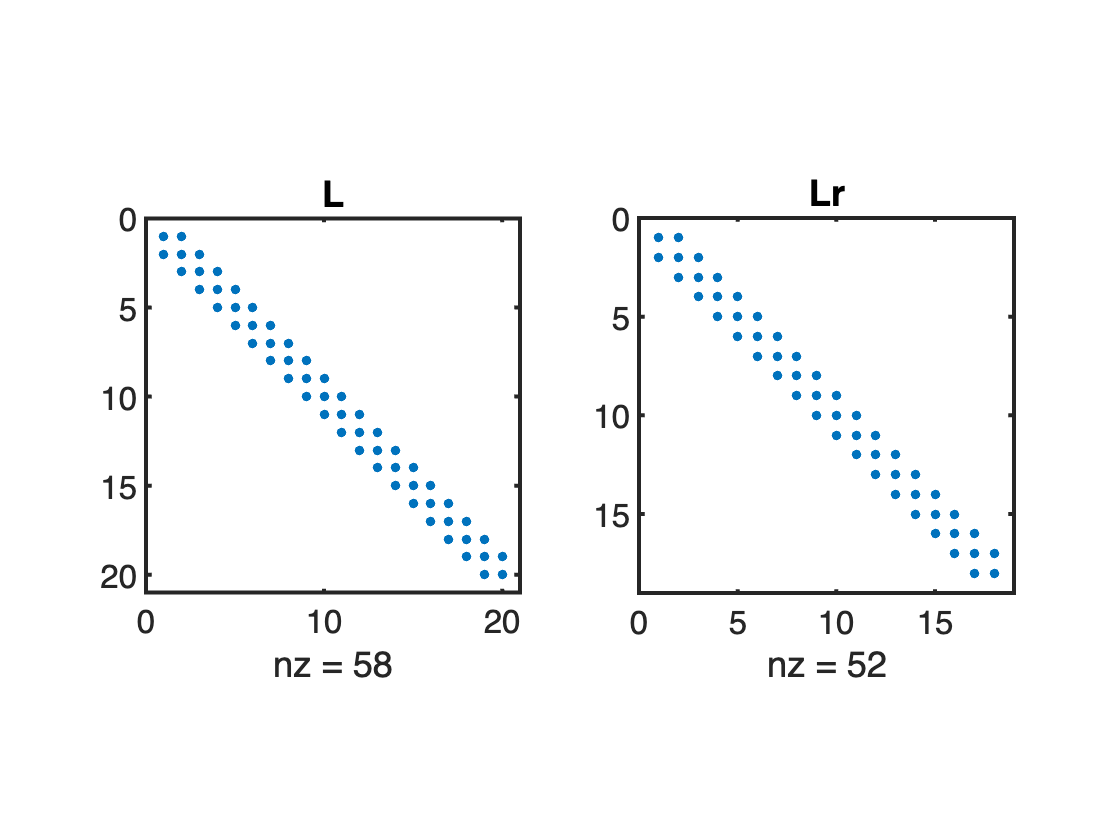

subplot 121
spy(L), title 'L'
subplot 122
spy(Lr), title 'Lr'

The reduced system matrix Lr is not singular anymore, because the constraints have been incorporated. This can be checked by estimating the condition number

condest(Lr)

ans = 180.0000

## Solving problem with homogeneous boundary conditions

 Solving a steady problem with homogeneous boundary conditions therefore requires 3 steps:

- Compute `N` and obtain `Lr` and `fsr`.

- Solve reduced problem: **h**`r`` = ``Lr``\``fsr`.

- Obtain full solution: **h**` = ``N``*``hr`.

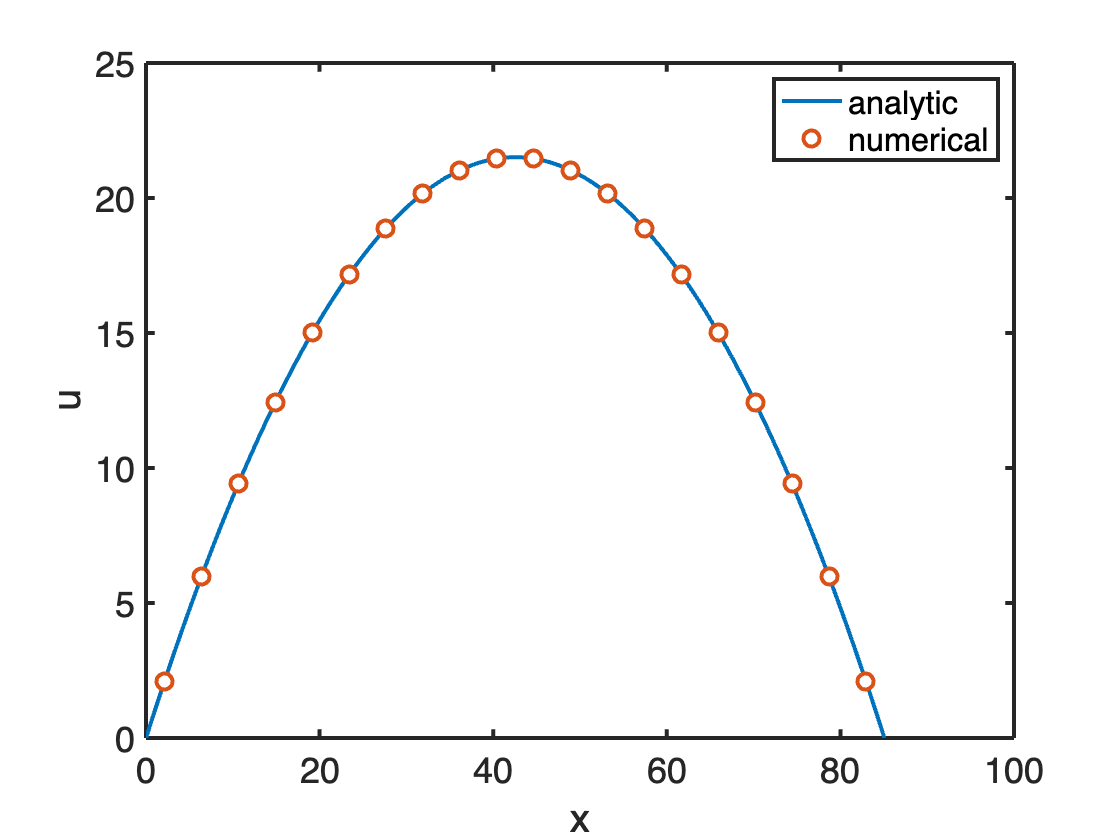

fs = qp/(b*K)*ones(Grid.Nx,1);
fsr = N'*fs;
hr = Lr\fsr;
h = N*hr;
h = h+ha_hom(Grid.xc(1),qp); % shift to account for BC
figure
plot(xa/1e3,ha_hom(xa,qp),'-',Grid.xc/1e3,h,'o','MarkerFaceColor','w','Markersize',8)
xlabel 'x', ylabel 'u'
legend('analytic','numerical')

Note, the boundary condition is set at the center of the first cell, which makes the solution look bad (first order error).

If we shift the solution upward by the appropriate amount the fit to the analytic solution is quite good.

# Heterogeneous constraints

We are interested in solving for the geotherm which requires heterogeneous, i.e., non-zero, BC's. In this case

 `B``*``h`` = ``g`,

where `g`` = [hD;hT]` is a vector containing the two boundary conditions.

clear all
Grid.xmin = 0; Grid.xmax = Length; Grid.Nx = 35;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
L = -D*G; fs = spalloc(Grid.Nx,1,0);

To obtain the solution of a problem with heterogeneous boundary conditions, we split the solution into a homogeneous and a particular solution as follows

`h`` = ``h0`` + ``hp`,

where the homogeneous solution solves `B``*``h0`` = ``0` as before and the particular solution solves `B``*``hp`` = ``g`. The solution then proceeds in three steps

- Find a particular solution that satisfies `B``*``hp`` = ``g`.

- Find the associated homogeneous solution, **h**`0`.

- Find total solution **h**` = ``h0`` + ``hp`.

## Find a particular solution

Note there are many possible particular solutions, here we just find the simplest one. Also not that **h**`p` does not need to satisfy `L``*``hp ``=`` fs` it only needs to satisfy the boundary conditions `B``*``hp ``=`` g`. Since the system is not square and `Nx > Nc` and `B` has only `Nc` entries we can again project into a reduced space of size `Nc`. 

It is natural to use `B` as projection matrix, so that **h**`pr`` = ``B``*``hp` and **h**`p`` = ``B'``*``hpr`. We derive the reduced system as follows

`B``*``hp`` = ``g`

`B``*(``B'``*``hpr``) = ``g`

`(``B``*``B'``)*``hpr`` = ``g`

`Br``*``hpr ``=`` g`

where the reduced constraint matrix is `Br`` = ``B``*``B'` is `Nc` by `Nc`. For the simple constraints we use here `Br` is simply the `Nc` by `Nc` identity matrix, so that **h**`pr`` = ``g`.  However, our definition is also valid for more general constraints so we'll stick with that. Once **h**`pr` is known the full particular solution can be recovered, **h**`p`` = ``B'``*``hpr`.

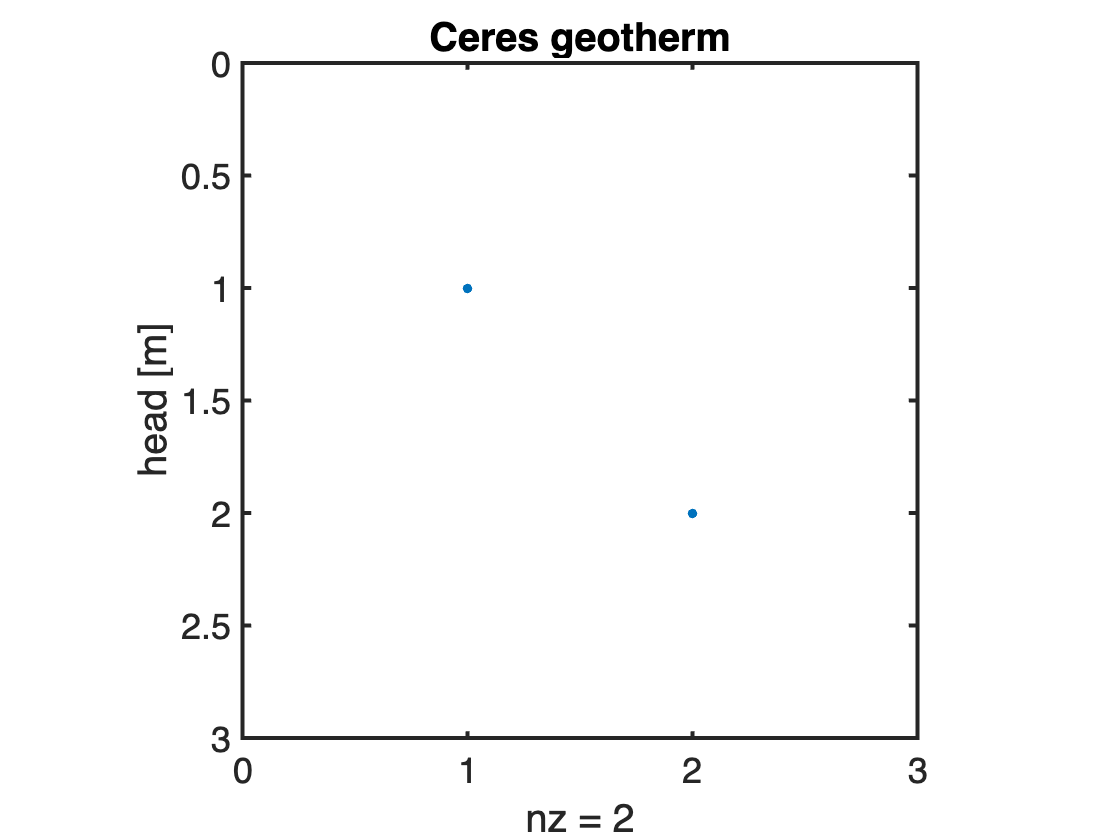

g = [hD;hT];
g = [ha(Grid.xc([1;Grid.Nx]),qp)];
dof_dir = [Grid.dof_xmin;Grid.dof_xmax];
B = I(dof_dir,:);
Br = B*B';
spy(Br)

hpr = Br\g;
hp = B'*hpr;

## Find associated homogeneous solution

Once up is known we find the associated homogeneous solution, h0, as follows

`L``*``h`` = ``fs`

`L``*(``h0+hp``) = ``fs`

`L``*``h0 ``=`` fs ``-`` L``*``hp`

`L``*``h0 ``=`` fs + fd`

where `fd = -L``*``hp `is a new source term due to heterogeneous Dirichlet BC's. But the problem can be solved with the nullspace projection for homogeneous problems as above. Combining the r.h.s. **f = fs + fd** we solve as follows

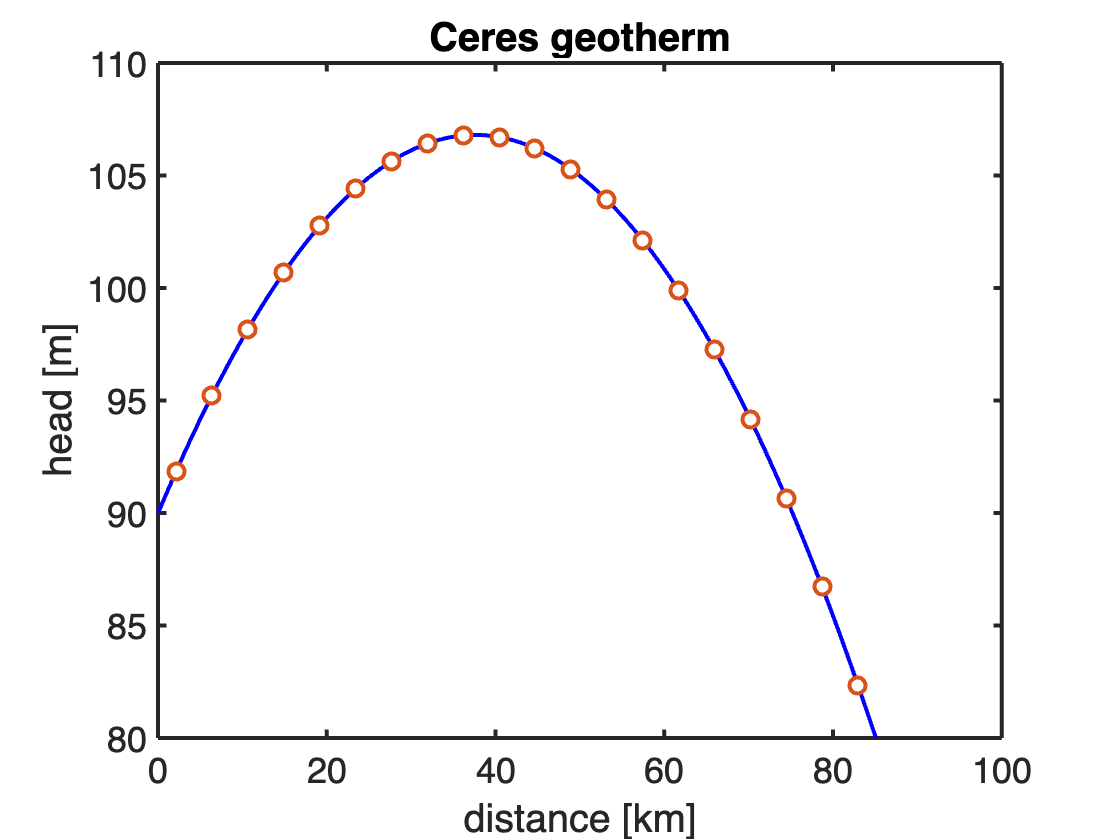

N = I; N(:,dof_dir)=[]; % simple/fast way to generate N without spnull()
fd = -L*hp;
f = fs + fd;
% Reduced system
fr = N'*f;
Lr = N'*L*N;
h0r = Lr\fr;
h0 = N*h0r;

% Total solution
h = h0 + hp;
figure
plot(xa/1e3,ha(xa,qp),'b-'), hold on
plot(Grid.xc/1e3,h,'o','MarkerFaceColor','w','Markersize',8)
xlabel 'distance [km]'
ylabel 'head [m]'
pbaspect([1 .8 1])
title('Ceres geotherm')

# Auxillary functions

This implementation of spnull() is taken from [Bruno Luong](https://www.mathworks.com/matlabcentral/profile/authors/390839-bruno-luong), thanks man!

function Z = spnull(S, varargin)
% Z = SPNULL(S)
% returns a sparse orthonormal basis for the null space of S, that is,
% S*Z has negligible elements, and Z'*Z = I
%
% If S is sparse, Z is obtained from the QR decomposition.
% Otherwise, Z is obtained from the SVD decomposition
%
% Bruno Luong <brunoluong@yahoo.com>
% History
%   10-May-2010: original version
%
% See also SPORTH, NULL, QR, SVD, ORTH, RANK

if issparse(S)
    [m n] = size(S);
    try
        [Q R E] = qr(S.'); %#ok %full QR
        if m > 1
            s = diag(R);
        elseif m == 1
            s = R(1);
        else
            s = 0;
        end
        s = abs(s);
        tol = norm(S,'fro') * eps(class(S));
        r = sum(s > tol);
        Z = Q(:,r+1:n);
    catch %#ok
        % sparse QR is not available on old Matlab versions
        err = lasterror(); %#ok
        if strcmp(err.identifier, 'MATLAB:maxlhs')
            Z = null(full(S), varargin{:});
        else
            rethrow(err);
        end
    end
else % Full matrix
    Z = null(S, varargin{:});
end

end

## set_defaults()

function [] = set_defaults()
    set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end